load fine_resnet50.mat; 

%Ricarico i dataset perché quelli salvati dalla rete hanno il percorso specifico di federico
imdsTrain = imageDatastore('dataset/TrainSet/','IncludeSubfolders',true,'LabelSource','foldernames');
imdsValidation = imageDatastore('dataset/ValSet','IncludeSubfolders',true,'LabelSource','foldernames');
imdsTest = imageDatastore('dataset/TestSet/','IncludeSubfolders',true,'LabelSource','foldernames');

inputSize = fine_resnet50.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);
augimdsTest = augmentedImageDatastore(inputSize(1:2),imdsTest);

% trovare gli indici delle righe in featTestMatrix che soddisfano la condizione
featTestMatrix = readmatrix('dataset/TestSet_features.txt', 'Delimiter', ' ');
idx = find(featTestMatrix(:,16)==1);
%idx = find(featTestMatrix(:,24)==1 | featTestMatrix(:,22)==0);

% eseguire la predizione solo per le righe selezionate
[YPred,scores] = classify(netTransfer,subset(augimdsTest,idx));
YPred = double(YPred(:,1));
YTest = YTest(idx);

numTestImages = numel(YPred);
imdsTest = subset(imdsTest,idx);


## Risultati predizione

Stampa di alcune img del test set con associata la label predetta e quella corretta.

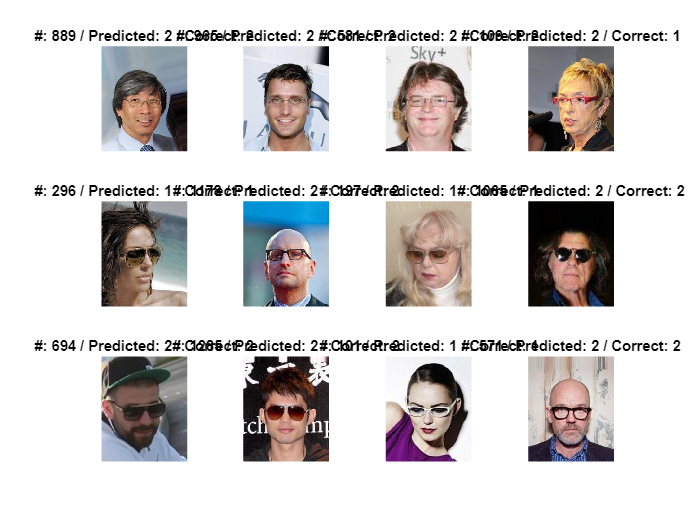

if printTestSet == 1
    idx = randi([1 numTestImages],1,12);
    figure
    for i = 1:numel(idx)
        subplot(3,4,i)
        I = readimage(imdsTest,idx(i));
        label = YPred(idx(i));
        corr = YTest(idx(i));
        imshow(I)
        title("#: "+idx(i)+" / Predicted: "+label+" / Correct: "+corr)
    end
end

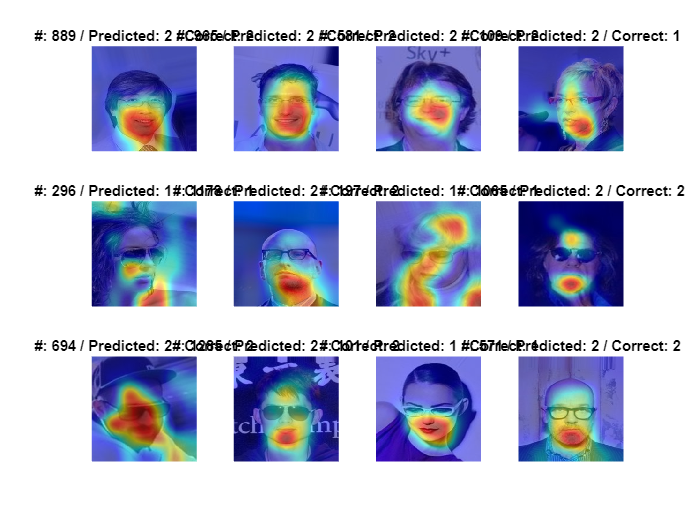


if printGradMap == 1
    figure
    for i = 1:numel(idx)
        subplot(3,4,i)
        I = imresize(readimage(imdsTest,idx(i)),inputSize(1:2));
        label = YPred(idx(i));
        corr = YTest(idx(i));
        imshow(I)
        hold on
        imagesc(gradCAM(netTransfer,I,label),'AlphaData',0.5)
        colormap jet
        title("#: "+idx(i)+" / Predicted: "+label+" / Correct: "+corr)
    end
end

## Matrice di confusione

Stampa della matrice di confusione. Ogni colonna della matrice rappresenta i valori predetti **(Output Class)** ed ogni riga rappresenta i valori reali **(Target Class)**.

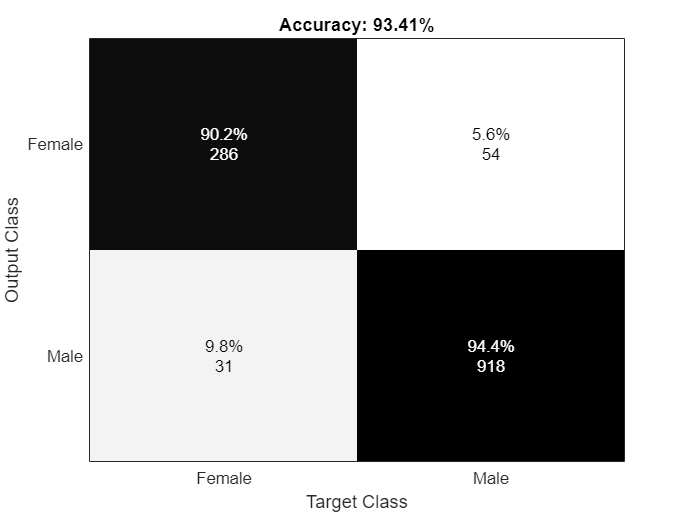

if printConfMatr == 1
    cm = confusionmat(YPred, YTest);
    labels = {'Female','Male'};
    figure
    plotConfMat(cm,labels)
end